**CAP5625** - Dr. De Giorgio

Amparo Godoy Pastore

December 1, 2023

# Programming Assignment 4

# 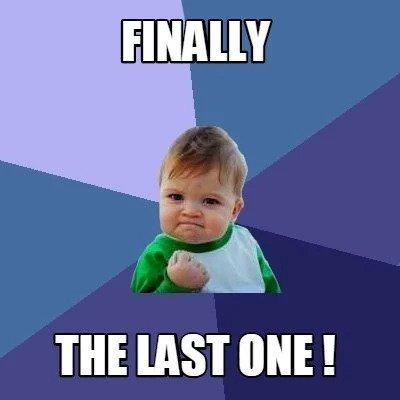

## Preliminaries

% parameters
p = 10;
steps = 10000;
alpha = 10^-5;

% data
test_df = readtable('TestData_N111_p10.csv');
train_df = readtable('TrainingData_N183_p10.csv');

% Learning rate alpha and tuning parameter lambda
lambda_values = [10^-4 10^-3 10^-2 10^-1 10^0 10^1 10^2 10^3 10^4];

% Number of classes (K)
ancestry_labels = table2array(unique(train_df(:, 11)));
K = length(ancestry_labels);

## Effect of tuning parameter on inferred regression coefficients

N = height(train_df);
% Indicator response matrix Y
Y = zeros(N, K);
y = table2array(train_df(:, 11));
for n = 1:N
    for k = 1:K
        if isequal(y{n}, ancestry_labels{k})
        Y(n, k) = 1;
        else
        Y(n, k) = 0;
        end
    end
end
    
% Augmented design matrix X
Xfeatures = train_df(:, 1:10);
Xintercept = table(ones(size(train_df, 1), 1));
X = [Xintercept, Xfeatures];
% Center and standardize each feature
for k = 2:size(X, 2) 
mean_val = mean(X(:, k));
std_val = std(X(:, k));
X(:, k) = (X(:, k) - mean_val) ./ std_val;
end
X = table2array(X);

% Algorithm
beta_hats = zeros(p + 1, 5, length(lambda_values));
for i = 1:length(lambda_values)
    lambda = lambda_values(i);
    beta_hats(:, :, i) = logistic_regression(X, Y, alpha, lambda, steps, p, K);
end

## Choosing the best tuning parameter

% Split the shuffled dataset into k folds
N = height(train_df);
shuffled_df = train_df(randperm(N), :);
k = 5;
folds = cell(1, k);
fold_size = floor(N / k);
for i = 1:k
    start_idx = (i - 1) * fold_size + 1;
    end_idx = min(i * fold_size, N);
    folds{i} = shuffled_df(start_idx:end_idx, :);
end

% Initialize matrices to save results
cv_errors = zeros(length(lambda_values), 5);
fold_errors = zeros(5, length(lambda_values));

% Loop over lambdas
for l = 1:length(lambda_values)
    lambda = lambda_values(l);

    % 5-fold cross-validation
    for f = 1:5

        % Split into train and test
        training_set = [];
        for j = 1:5
            if ~isequal(j, f)
                training_set = [training_set; folds{j}];
            end
        end  

        validation_set = folds{f};
        % Standardize features
        % Center the output variable and standardize the features for training and validation sets
        % Response vector
        N_train = height(training_set);
        N_validation = height(validation_set);

        train_Y = zeros(N_train, 5);
        test_Y = zeros(N_validation, 5);

        train_y = table2array(training_set(:, 11));
        test_y = table2array(validation_set(:, 11));

        for n = 1:N_train
            for k = 1:K
                if isequal(train_y{n}, ancestry_labels{k})
                    train_Y(n, k) = 1;
                else
                    train_Y(n, k) = 0;
                end
            end
        end

        for n = 1:N_validation
            for k2 = 1:K    
                if isequal(test_y{n}, ancestry_labels{k2})
                    test_Y(n, k2) = 1;
                else
                    test_Y(n, k2) = 0;
                end
            end
        end

        center_Y = mean(train_Y);
        train_Y = train_Y - center_Y;
        test_Y = test_Y - center_Y;
    
        % Design Matrix
        % Augmented design matrix
        train_X = training_set(:, 1:10);
        test_X = validation_set(:, 1:10);
    
        trainXintercept = table(ones(size(training_set, 1), 1));
        testXintercept = table(ones(size(validation_set, 1), 1));
        train_X = [trainXintercept, train_X];     
        test_X = [testXintercept, test_X]; 
        
        % Center and standardize each feature
        for k = 2:size(train_X, 2) 
            center_X = mean(train_X(:, k));
            std_X = std(train_X(:, k));
            train_X(:, k) = (train_X(:, k) - center_X) ./ std_X;
            test_X(:, k) = (test_X(:, k) - center_X) ./ std_X;
        end
        
        train_X = table2array(train_X);
        test_X = table2array(test_X);

        % Run algorithm
        B_hat = logistic_regression(train_X, train_Y, alpha, lambda, steps, p, K);
        
        % Predict
        U_test = exp(test_X * B_hat);

        % Compute normalized class probability matrix for the test set
        P_test = U_test ./ sum(U_test, 2);

        % Choose the class with the highest probability as the predicted class
        [~, predicted] = max(P_test, [], 2);

        % Compute cross-entropy error on the validation set
        Nm = size(test_Y, 1);
        cross_entropy = -1/Nm * sum(log10(P_test(sub2ind(size(P_test), (1:Nm)', predicted))));

        % Save categorical cross-entropy for each fold
        fold_errors(f, l) = cross_entropy;
    end
end
% Calculate cross-validation error
cv_errors = mean(fold_errors, 1);

## Retraining model with optimal parameter

% Find the index of the minimum cross-validation error and retreive best
% lambda
[min_cv_error, min_cv_index] = min(cv_errors);
best_lambda = lambda_values(min_cv_index);

% Retrain with optimal lambda on all observations
optimal_B_hats = logistic_regression(X, Y, alpha, best_lambda, steps, p, K);

% Make predictions on test individuals
% Extract features
testX = test_df(:, 1:10);

% Augment the design matrix
testXintercept = table(ones(size(testX, 1), 1));
testX = [testXintercept, testX];

% Standardize features
for k = 2:size(testX, 2)
    centerX = mean(testX(:, k));
    stdX = std(testX(:, k));
    testX(:, k) = (testX(:, k) - centerX) ./ stdX;
end
testX = table2array(testX);

% Predict probabilities for each class for each sample
Utest = exp(testX * optimal_B_hats);
Ptest = Utest ./ sum(Utest, 1);

% Determine the most probable ancestry label for each sample
[~, predicted_labels] = max(Ptest, [], 2);

## Algorithm 1 implementation

function B_hat = logistic_regression(X, Y, alpha, lambda, steps, p, K)

    % Intialize dimensional parameter matrix
    B = zeros(p + 1, K);

    for i = 1:steps
        % Compute matrix U
        U = exp(X * B);
        
        % Compute matrix P
        P = U ./ sum(U, 1);
        
        % Generate intercept matrix
        Z = zeros(p + 1, K);
        Z(1, :) = B(1, :);

        % Update the parameter matrix
        B = B + alpha * (X.' * (Y - P) - 2 * lambda * (B - Z));

    end
    
    B_hat = B;

end

## Discussion

*    How do the class label probabilities differ for the Mexican and African American samples when compared to the class label probabilities for the unknown samples? Are these class probabilities telling us something about recent history? Explain why these class probabilities are reasonable with respect to knowledge of recent history.*

    We have probabilities associated with various ancestry labels for both Mexican and the Unknown labels. Meanwhile, the African American sample consistently shows a higher probability for the African class label.

    These class probabilities may hint at historical migration patterns, intermixing, or population movements. For instance, considering the historical context of the Americas, including colonization, the African diaspora, and migrations from Europe and Asia, we might expect unique genetic signatures for Mexican and African American populations. Mexico's population, for example, is known for its mixture of indigenous, European (primarily Spanish), and African ancestry due to historical events like colonization and the African diaspora.

    Mexican samples might show a higher probability for Native American ancestry due to the indigenous population's presence in Mexico before colonization. For African American samples, there might be higher probabilities associated with African ancestry due to the transatlantic slave trade and historical migrations from Africa to the Americas. Comparatively, the unknown samples might show more diverse or evenly distributed probabilities across ancestries due to not being specifically categorized or attributed to a particular known population.

    These class probabilities align with known historical events and the mixing of ancestries that occurred in these populations due to colonization, slavery, and migrations. Recent history involving the movement and intermingling of populations from various regions has influenced the genetic makeup of Mexican and African American populations, hence resulting in distinct probability patterns.